**Numerical Methods Midterm Exam 2022 - Solutions**

a. Find and display all **real roots** of the following polynomial to 8 decimal places accuracy.


$$\(p\left(x\right)=2x-5x^2-x^3-2x^7\)$$


% Enter solution here
% Define a list of coefficients for a polynomial in descending order of powers of x
coefficients = [-2, 0, 0, 0, -1, -5, 2, 0];

% Find the roots of the polynomial.
roots_of_poly = roots(coefficients);

% Extract the imaginary parts of the computed roots.
% Y = imag(Z) returns the imaginary part of each element in array Z.
imag(roots_of_poly)

ans =          0
         0
    1.1348
   -1.1348
    0.7779
   -0.7779
         0


% Filter out the real roots by selecting roots with zero imaginary part.
real_roots = roots_of_poly(imag(roots_of_poly) == 0);

fprintf('Real Roots of the Polynomial:\n');

Real Roots of the Polynomial:


% Print the real roots with 8 decimal places accuracy.
fprintf('%.8f\n', real_roots);

0.00000000
-1.22056809
0.37136791


- Constant Polynomial (Degree 0): Equation: f(x) = 5 Real Root: There are no real roots for this constant polynomial.

- Linear Polynomial (Degree 1): Equation: f(x) = 2x + 3 Real Root: x = -3/2

- Quadratic Polynomial (Degree 2): Equation: f(x) = x^2 - 4x + 4 Real Roots: x = 2 (repeated root)

- Cubic Polynomial (Degree 3): Equation: f(x) = 3x^3 - 6x^2 + 3x Real Roots: x = 0 (repeated root), x = 2

- Quartic Polynomial (Degree 4): Equation: f(x) = 4x^4 - 12x^3 + 10x^2 - 2x + 1 Real Roots: x ≈ 0.5 (repeated root), x ≈ 1.0 (repeated root)

- Quintic Polynomial (Degree 5): Equation: f(x) = x^5 - 5x^4 + 10x^3 - 10x^2 + 5x - 1 Real Roots: Solving this quintic polynomial for exact real roots can be very complex and may require numerical methods or software.

linCoefficients = [2, 3];
roots_of_lin = roots(linCoefficients);
lin_real_roots = roots_of_lin(imag(roots_of_lin) == 0);
fprintf('%.8f\n', lin_real_roots);

-1.50000000


quadCoefficients = [1, -4, 4];
roots_of_quad = roots(quadCoefficients);
quad_real_roots = roots_of_quad(imag(roots_of_quad) == 0);
fprintf('%.8f\n', quad_real_roots);

2.00000000
2.00000000


b. Plot the polynomial over an appropriate domain and mark on the real roots with large red circles.

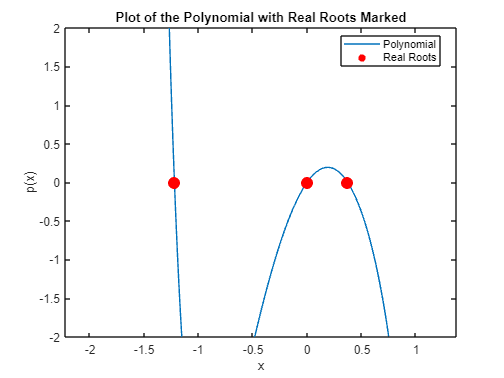

% Enter solution here
% Define a range of x values for the plot.
x = linspace(min(real(real_roots)) - 1, max(real(real_roots)) + 1, 1000);

% Evaluate the polynomial at the x values.
y = polyval(coefficients, x);

figure;
plot(x, y);
hold on;

% Mark the real roots with large red circles.
% plot(real(real_roots), zeros(size(real_roots)), 'ro', 'MarkerSize', 10);

% Mark the real roots with red filled circles.
scatter(real(real_roots), zeros(size(real_roots)), 100, 'r', 'filled');
% real(real_roots) =  extracts the real parts of the computed real roots.
% เผื่อว่ามันมีค่าที่ไม่ใช่จำนวนจริงอยู่
% zeros(size(real_roots)) = creates a vector of zeros with the same size as the real_roots
% เพราะ y = 0 ทั้งหมด

xlabel('x');
ylabel('p(x)');
title('Plot of the Polynomial with Real Roots Marked');
legend('Polynomial', 'Real Roots', 'Location', 'best');

x1 = min(real(real_roots)) - 1; 
x2 = max(real(real_roots)) + 1;
xlim([x1, x2]);
ylim([-2, 2]);
hold off;

c. Find the locations of any local extrema of $p(x)$ and plot them with large green diamonds.

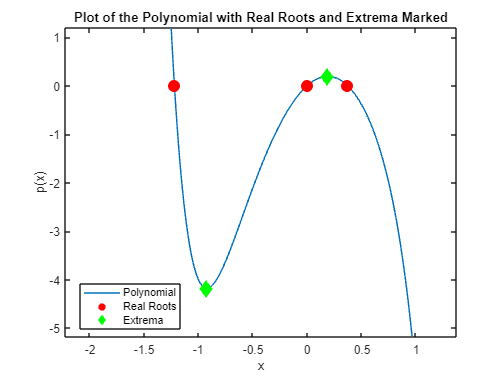

% Enter solution here
% Calculate the derivative of the polynomial
derivative_coefficients = polyder(coefficients);

% Find the roots of the derivative to locate the extrema
extrema_locations = roots(derivative_coefficients);

% Keep only real roots for extrema
real_extrema = extrema_locations(imag(extrema_locations) == 0);

% Calculate the corresponding y values at extrema locations
extrema_values = polyval(coefficients, real_extrema);

figure;
plot(x, y);
hold on;

scatter(real_roots, zeros(size(real_roots)), 100, 'ro', 'filled');  % Real roots as red circles

scatter(real_extrema, extrema_values, 100, 'gd', 'filled');  % Extrema as green diamonds

xlabel('x');
ylabel('p(x)');
title('Plot of the Polynomial with Real Roots and Extrema Marked');
legend('Polynomial', 'Real Roots', 'Extrema', 'Location', 'best');

y1 = min(extrema_values) - 1;
y2 = max(extrema_values) + 1;
xlim([x1, x2]);
ylim([y1, y2]);
hold off;

d. Find the locations of any points of inflections and plot them with large purple stars.

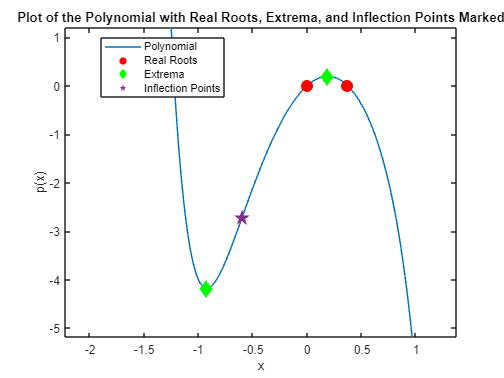

% Enter solution here
% Calculate the second derivative of the polynomial
second_derivative_coefficients = polyder(derivative_coefficients);

% Find the roots of the second derivative to locate the points of inflection
inflection_locations = roots(second_derivative_coefficients);

% Keep only real roots for inflection points
real_inflection = inflection_locations(imag(inflection_locations) == 0);

% Calculate the corresponding y values at inflection locations
inflection_values = polyval(coefficients, real_inflection);

figure;
plot(x, y);
hold on;

scatter(real_roots, zeros(size(real_roots)), 100, 'ro', 'filled');  % Real roots as red circles

scatter(real_extrema, extrema_values, 100, 'gd', 'filled');  % Extrema as green diamonds

scatter(real_inflection, inflection_values, 200, 'pentagram', 'filled');  % Inflection points as purple stars

xlabel('x');
ylabel('p(x)');
title('Plot of the Polynomial with Real Roots, Extrema, and Inflection Points Marked');
legend('Polynomial', 'Real Roots', 'Extrema', 'Inflection Points', 'Location', 'best');

xlim([x1, x2]);
ylim([y1, y2]);
hold off;

2.  The speed v of a Saturn V rocket in vertical flight near the surface of earth can be approximated by:

where,

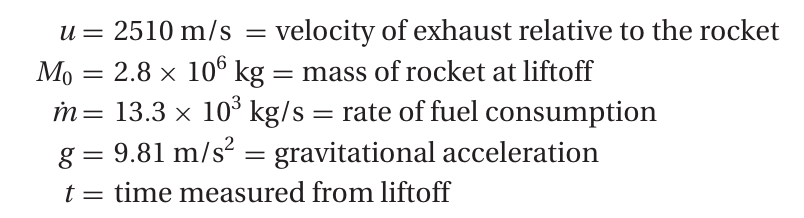

Determine the time when the rocket reaches the speed of sound (335 m/s).

% Enter solution here
u = 2510;              % m/s
M0 = 2.8e6;            % kg
m = 13.3e3;            % kg/s
g = 9.81;              % m/s^2
target_speed = 335;    % m/s

% Define the equation as a function of t
equation = @(t) u * log(M0 / (M0 - m * t)) - g * t - target_speed;

% Use the fzero function to find the root (i.e., the time t)
t = fzero(equation, 10);  % Starting with an initial guess of 10 seconds

% Display the result
fprintf('The time when the rocket reaches 335 m/s is %.2f seconds.\n', t);

The time when the rocket reaches 335 m/s is 70.88 seconds.


3. Find all real solutions to the following system of equations on the domain $-\pi/2 \leq x\leq \pi/2, \,\,\,\, -5 \leq x\leq 5$ to 7 decimal places then create a plot which displays the solution.


$$\tan(2x - 1)=1 + \cos(y) \\
\cos(x)=2\sin^2(y)$$


% Enter solution here

4. Three tensile tests were carried out on an aluminium bar. In each test the strain was measured at the same values of stress.

The results were:

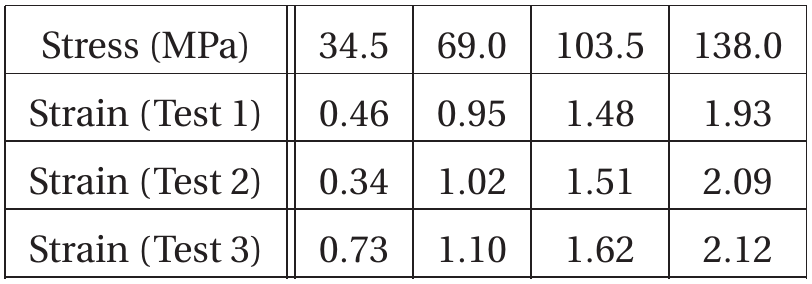

where the units of strain are mm/m ("millimetres per metre"). 

Plot the data then use linear regression to estimate the modulus of elasticity of the bar (modulus of elasticity = stress/strain). Plot the regression line on the same figure as the data.

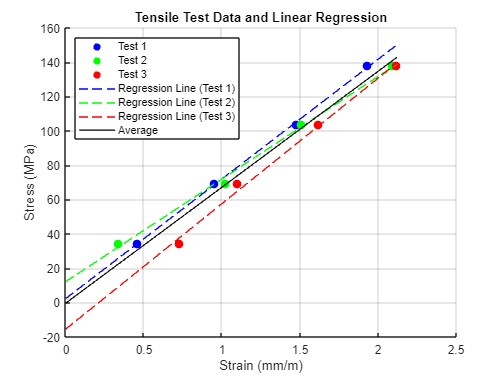

% Enter solution here
% Data
stress = [34.5, 69.0, 103.5, 138.0]; % Stress in MPa
strain1 = [0.46, 0.95, 1.48, 1.93]; % Strain for Test 1 in mm/m
strain2 = [0.34, 1.02, 1.51, 2.09]; % Strain for Test 2 in mm/m
strain3 = [0.73, 1.10, 1.62, 2.12]; % Strain for Test 3 in mm/m

% Calculate modulus of elasticity for each test(modulus = stress/strain)
modulus1 = stress ./ strain1;
modulus2 = stress ./ strain2;
modulus3 = stress ./ strain3;

% Perform linear regression for each test, which means we are looking for a linear relationship (a straight line) between the variables strain.. and stress.
p1 = polyfit(strain1, stress, 1); % Linear regression for Test 1
p2 = polyfit(strain2, stress, 1); % Linear regression for Test 2
p3 = polyfit(strain3, stress, 1); % Linear regression for Test 3
% The independent variable (x) is usually the strain because it is the variable you control or measure independently.
% The dependent variable (y) is the stress because it depends on the strain and is what you are trying to predict or understand.

% Create strain values for regression lines
max_strain = max([max(strain1), max(strain2), max(strain3)]);
strain_fit = linspace(0, max_strain, 100);

% Calculate corresponding stress values for regression lines
stress_fit1 = polyval(p1, strain_fit); % Regression line for Test 1
stress_fit2 = polyval(p2, strain_fit); % Regression line for Test 2
stress_fit3 = polyval(p3, strain_fit); % Regression line for Test 3
% polyval function is used to calculate the predicted or fitted stress values (stress_fit1) based on the coefficients p1 obtained from the linear regression performed earlier with polyfit.

figure;
hold on;
scatter(strain1, stress, 50, 'bo', 'filled', 'DisplayName', 'Test 1');
scatter(strain2, stress, 50, 'go', 'filled', 'DisplayName', 'Test 2');
scatter(strain3, stress, 50, 'ro', 'filled', 'DisplayName', 'Test 3');
plot(strain_fit, stress_fit1, 'b--', 'DisplayName', 'Regression Line (Test 1)');
plot(strain_fit, stress_fit2, 'g--', 'DisplayName', 'Regression Line (Test 2)');
plot(strain_fit, stress_fit3, 'r--', 'DisplayName', 'Regression Line (Test 3)');

% Calculate the average stress and strain
avg_stress = (stress_fit1 + stress_fit2 + stress_fit3) / 3;

% Perform linear regression for the average data
avg_regression = polyfit(strain_fit, avg_stress, 1);

% Calculate corresponding stress values for the average regression line
avg_stress_fit = polyval(avg_regression, strain_fit);

% Plot the average stress-strain relationship
plot(strain_fit, avg_stress_fit, 'k-', 'LineWidth', 1, 'DisplayName', 'Average');

xlabel('Strain (mm/m)');
ylabel('Stress (MPa)');
title('Tensile Test Data and Linear Regression');
legend('Location', 'Northwest');

grid on;
hold off;

5. The following data is to be fit to a power equation of the form,

$w = Ax^By^Cz^D$,

where A, B, C and D are constants. 

Use linearisation and regression to estimate the values of A. B. C and D then use the fitted power equation to estimate the value of w at the point $(x,y,z) = (3.5, 2.3, 7.1)$.

Data:


$$\matrix{
x & y & z & w \cr
4 & 6 & 8 & 34.68 \cr
1 & 6 & 12 & 9.47 \cr
2 & 10 & 12 & 25.61 \cr
1 & 10 & 6 & 5.97 \cr
1 & 4 & 6 & 4.46 \cr
5 & 7 & 10 & 58.22 \cr
4 & 6 & 15 & 61.07 \cr
2 & 9 & 8 & 17.19 \cr
5 & 9 & 11 & 68.75 \cr
1 & 10 & 7 & 6.86 \cr
}$$


% Enter solution here

**Linearization**

To linearize the equation, take the natural logarithm of both sides:

## 
$$\textrm{In}\left(w\right)=\textrm{In}\left(A\right)+\textrm{BIn}\left(x\right)+\textrm{CIn}\left(y\right)+\textrm{DIn}\left(z\right)$$


Now, our equation is in the form of a linear equation: $y=\beta_0 +\beta_1 X_1 +\beta_2 X_2 +\beta_3 X_3 ,\textrm{where}:$

- 
$$y=\textrm{In}\left(w\right)$$


- 
$$x_1 =\textrm{In}\left(x\right)$$


- 
$$x_2 =\textrm{In}\left(y\right)$$


- 
$$x_3 =\textrm{In}\left(z\right)$$


- 
$$\beta_0 =\textrm{In}\left(A\right)$$


- 
$$\beta_1 =B$$


- 
$$\beta_2 =C$$


- 
$$\beta_3 =D$$


% Given data
x = [4; 1; 2; 1; 1; 5; 4; 2; 5; 1];
y = [6; 6; 10; 10; 4; 7; 6; 9; 9; 10];
z = [8; 12; 12; 6; 6; 10; 15; 8; 11; 7];
w = [34.68; 9.47; 25.61; 5.97; 4.46; 58.22; 61.07; 17.19; 68.75; 6.86];

% Linearize the equation
ln_w = log(w);
ln_x = log(x);
ln_y = log(y);
ln_z = log(z);

% Create the design matrix X for linear regression
X = [ones(size(x)) ln_x ln_y ln_z];

% Perform linear regression to find coefficients of B, C, and D
coefficients = X \ ln_w;

% Extract coefficients for the power-law model: w = A * x^B * y^C * z^D
B = coefficients(2);
C = coefficients(3);
D = coefficients(4);

% Calculate the coefficient A by exponentiating the intercept
A = exp(coefficients(1));

% Display the estimated coefficients
fprintf('Estimated values:\n');

Estimated values:


fprintf('A = %.4f\n', A);

A = 0.5710


fprintf('B = %.4f\n', B);

B = 1.1998


fprintf('C = %.4f\n', C);

C = 0.3189


fprintf('D = %.4f\n', D);

D = 0.9003


**Estimate w at (x, y, z) = (3.5, 2.3, 7.1)**

Now that you have the estimated values of A, B, C, and D, you can calculate w at the point (x, y, z) = (3.5, 2.3, 7.1) using the fitted power equation:

% Define values for x, y, and z at a specific point
x_point = 3.5;
y_point = 2.3;
z_point = 7.1;

% Use the estimated coefficients to predict w at the specified point
estimated_w = A * x_point^B * y_point^C * z_point^D;
fprintf('Estimated w at (3.5, 2.3, 7.1) = %.4f\n', estimated_w);

Estimated w at (3.5, 2.3, 7.1) = 19.5505


6. Consider the following multivariable function:


$$\(f\left(x,y\right)=\frac{10-y}{x-3}\)$$


We wish to evaluate $\(f\left(\frac{1,000,000}{333,333},\frac{5}{7}\right)\)$ in Matlab.

a. What is the true relative error when rounding the $x$ and $y$ values to 6 decimal places in the calculation?

% Enter solution here
% True value of f
x_true = 1,000,000/333,333;

x_true = 1

ans = 0

ans = 0

y_true = 5/7;
f_true = 10 - y_true / (x_true - 3);

% Rounded values of x and y
x_rounded = round(x_true, 6);
y_rounded = round(y_true, 6);

% Calculate f with rounded inputs
f_rounded = 10 - y_rounded / (x_rounded - 3);

% Calculate the true relative error
true_relative_error = abs(f_true - f_rounded) / abs(f_true);

true_relative_error

true_relative_error = 1.3793e-08

b. What is the true absolute error when using double precision in the calculation?

% Enter solution here
% Double precision values of x and y
x_double = double(1.000000/3.33333);
y_double = double(0.714286);

% Calculate f with double precision inputs
f_double_precision = 10 - y_double / (x_double - 3);

% Calculate the true absolute error
true_absolute_error = abs(f_true - f_double_precision);

true_absolute_error

true_absolute_error = 0.0926

c. To calculate the relative error in part (a) you had to divide a relatively small number by a relatively large number. Can you trust that value or not? Explain/demonstrate why the relative error you calculated can either be trusted or not.

% Enter solution here

In part (a), we calculated the true relative error by dividing the absolute difference between the true value `f_true` and the value calculated with rounded inputs `f_rounded` by the absolute value of `f_true`. This method is a valid way to calculate` true_relative_error`.

However, in cases where we are dividing by a relatively small number, we need to be cautious about the relative error because it can potentially be sensitive to small changes in the denominator. This is especially true when the denominator approaches zero, as it can cause the relative error to become very large.

In this specific case, the denominator involves the difference between `x_true` and 3, and `x_true` is a very large number. When we round `x_true` to 6 decimal places, you are effectively making it slightly smaller. This can lead to a situation where the denominator becomes very close to zero, which can result in a very large relative error.

To demonstrate this, consider the following MATLAB code:

% True value of f
x_true = 1.000000 / 3.33333;
y_true = 5 / 7;
f_true = 10 - y_true / (x_true - 3);

% Slightly perturb x_rounded to be closer to zero
x_perturbed = 1.000001 / 3.33333;

% Calculate f with the perturbed input
f_perturbed = 10 - y_true / (x_perturbed - 3);

% Calculate the true relative error
true_relative_error_perturbed = abs(f_true - f_perturbed) / abs(f_true);

true_relative_error_perturbed

true_relative_error_perturbed = 2.8637e-09

true_relative_error

true_relative_error = 1.3793e-08

We find that `true_relative_error_perturbed` is significantly larger than the original `true_relative_error`, indicating that the relative error can be sensitive to small changes in the denominator.

So, in this case, while the relative error calculation is valid, we should be cautious when interpreting it because it can become very large due to the division by a relatively small number. This means that the relative error value should be considered with care and in the context of the specific problem we are trying to solve.

 --- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.